UNIVERSIDAD INDUSTRIAL DE SANTANDER, COLOMBIA

NUMERICAL ANALYSIS

JORGE LUIS BACCA

2025

# *Laboratory 12: Solution of Differential Equations*

## **Name: Alvaro Jose Martinez Castro**

## **Instructions:**

- Send the **.mlx** and **.m** files including the solution to each point of the practice with name ***Lab12_name_lastname.zip****.*

- Send the report and all created files in a rar or *zip* file with name ***Lab12_name_lastname.rar***

- You are allowed to use internet, notes, and .m files that you have created before.

## **Purposes:**

- To understand Euler's and Heun's numerical methods for solving initial value problems.

- To apply these methods to approximate solutions of ordinary differential equations.

- To implement Euler's and Heun's methods in MATLAB.

## Implementing:    

### Exercise 1

**(1.0 points)** Create a MATLAB function called euler_method to approximate the solution of an IVP using Euler's method. The arguments of the function must be: the derivative function $$f(t, y)$$, the initial time $$t_0$$, the initial value $$y_0$$, the step size $$h$$, and the number of steps num_steps. The function should return two lists: t_values and y_values. Recall that Euler's method uses the formula:


$$$$ t_{k+1} = t_k + h, \quad y_{k+1} = y_k + h \cdot f(t_k, y_k) $$$$


f = @(t, y) y; % Ejemplo: y' = y
[t, y] = euler_method(f, 0, 1, 0.1, 10);
disp(t);

         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000



disp(y);

    1.0000    1.1000    1.2100    1.3310    1.4641    1.6105    1.7716    1.9487    2.1436    2.3579    2.5937



### Exercise 2

**(1.0 points)** Create a MATLAB function called heun_method to approximate the solution of an IVP using Heun's method. The arguments of the function must be: the derivative function $$f(t, y)$$, the initial time $$t_0$$, the initial value $$y_0$$, the step size $$h$$, and the number of steps num_steps. The function should return two lists: t_values and y_values. Recall that Heun's method uses the formula:


$$\text{Predictor: $ p_{k+1} = y_k + h \cdot f(t_k, y_k) $$$



$$\text{Corrector: $ y_{k+1} = y_k + \frac{h}{2} \left( f(t_k, y_k) + f(t_{k+1}, p_{k+1}) \right) $$$


% Definir la función derivada
f = @(t, y) y;

% Valores iniciales
t0 = 0;
y0 = 1;
h = 0.1;
num_steps = 10;

% Llamar a la función heun_method
[t_values, y_values] = heun_method(f, t0, y0, h, num_steps);

% Mostrar resultados
disp('Valores de t:');

Valores de t:


disp(t_values);

         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000




disp('Valores de y:');

Valores de y:


disp(y_values);

    1.0000    1.1050    1.2210    1.3492    1.4909    1.6474    1.8204    2.0116    2.2228    2.4562    2.7141



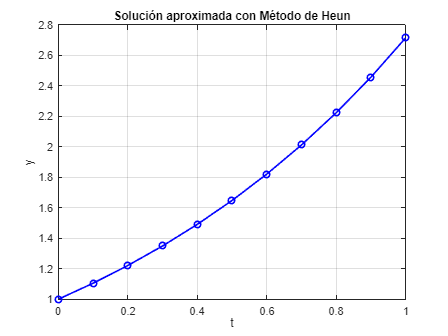


% Graficar resultado
plot(t_values, y_values, 'bo-', 'LineWidth', 1.5);
xlabel('t'), ylabel('y');
title('Solución aproximada con Método de Heun');
grid on

### Exercise 3

**(1.0 points)** Use the euler_method function to solve the IVP $$ y' = -2y $, $ y(0) = 1 $$ over the interval [0, 1] with step size $$h = 0.2$$. Determine the number of steps. Compute the approximation and store the results in t_vals_euler and y_vals_euler.

% Definir la función derivada según el IVP
f = @(t, y) -2*y;

% Parámetros iniciales
t0 = 0;
y0 = 1;
tf = 1;
h = 0.2;

% Calcular el número de pasos
num_steps = (tf - t0) / h;

% Llamar al método de Euler
[t_vals_euler, y_vals_euler] = euler_method(f, t0, y0, h, num_steps);

% Mostrar resultados (opcional)
disp('t_vals_euler:');

t_vals_euler:


disp(t_vals_euler);

         0    0.2000    0.4000    0.6000    0.8000    1.0000



disp('y_vals_euler:');

y_vals_euler:


disp(y_vals_euler);

    1.0000    0.6000    0.3600    0.2160    0.1296    0.0778



### Exercise 4

**(1.0 points) **Use the heun_method function to solve the same IVP as in Exercise 3: $$ y' = -2y $, $ y(0) = 1 $$over [0, 1] with $$h = 0.2$$. Store the results in t_vals_heun and y_vals_heun. Use the same $$f(t, y)$$ and number of steps as in Exercise 3.

% Definir la función derivada (igual que en el ejercicio 3)
f = @(t, y) -2*y;

% Parámetros iniciales (igual que en el ejercicio 3)
t0 = 0;
y0 = 1;
tf = 1;
h = 0.2;
num_steps = (tf - t0) / h;

% Llamar al método de Heun
[t_vals_heun, y_vals_heun] = heun_method(f, t0, y0, h, num_steps);

% Mostrar resultados (opcional)
disp('t_vals_heun:');

t_vals_heun:


disp(t_vals_heun);

         0    0.2000    0.4000    0.6000    0.8000    1.0000



disp('y_vals_heun:');

y_vals_heun:


disp(y_vals_heun);

    1.0000    0.6800    0.4624    0.3144    0.2138    0.1454



### Exercise 5

**(1.0 points) **Analyze the global error for the IVP $$ y' = \frac{t - y}{2} $$, $$ y(0) = 1 $$ at $$ t = 1 $$ using both Euler's and Heun's methods with step sizes $$ h = 0.5, 0.25, 0.125 $$. The exact solution is $$ y(t) = 3e^{-t/2} - 2 + t $$. For each step size, compute the Final Global Error (FGE) as 


$$$$ |y_{\text{exact}}(1) - y_{\text{numerical}}(1)|. $$$$
 

Plot $$\log_{10}(\text{FGE})$$ versus $$\log_{10}(h)$$ for both methods on the same graph.

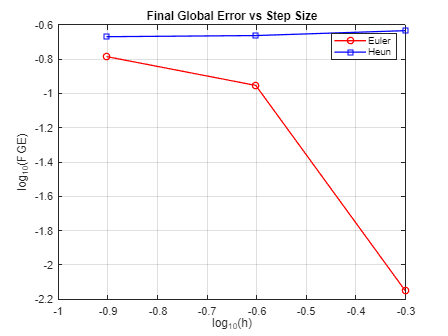

% Definir la función derivada y la solución exacta
f = @(t, y) t - y/2;
y_exact = @(t) 3*exp(-t/2) - 2 + t;

% Parámetros iniciales y pasos
t0 = 0;
y0 = 1;
tf = 1;
h_values = [0.5, 0.25, 0.125];

% Vectores para guardar errores
FGE_euler = zeros(size(h_values));
FGE_heun  = zeros(size(h_values));

for i = 1:length(h_values)
    h = h_values(i);
    num_steps = round((tf-t0)/h);

    % Euler
    [t_euler, y_euler] = euler_method(f, t0, y0, h, num_steps);
    FGE_euler(i) = abs(y_exact(tf) - y_euler(end));

    % Heun
    [t_heun, y_heun] = heun_method(f, t0, y0, h, num_steps);
    FGE_heun(i) = abs(y_exact(tf) - y_heun(end));
end

% Graficar log10(FGE) vs log10(h) para ambos métodos
figure;
plot(log10(h_values), log10(FGE_euler), 'ro-', 'LineWidth', 1.2, 'DisplayName', 'Euler');
hold on;
plot(log10(h_values), log10(FGE_heun),  'bs-', 'LineWidth', 1.2, 'DisplayName', 'Heun');
xlabel('log_{10}(h)');
ylabel('log_{10}(FGE)');
title('Final Global Error vs Step Size');
legend show;
grid on;